%% Elosztott UEP Viterbi vs. LTE Turbo Kód
% 1. Rendszer: A te "Horgonyos" UEP megoldásod (K=7 RSC, 80 BPSK / 400 QPSK)
% 2. Rendszer: Valódi LTE Turbo Kód (K=4, 2x RSC, Keverő, 4 iteráció)

clear; clc; close all;

%% 1. Rendszer Paraméterek
dataLen = 1000;         % Hasznos adatbitek száma
max_keret = 200;        % A Turbo dekódoló lassabb, így 200 keret elég a demóhoz
EbNo_dB_array = 0:0.5:4.5; % Energia/Bit (Eb/No) tartomány

% --- UEP (Horgonyos) Rendszer Beállításai ---
K_uep = 7;
trellis_uep = poly2trellis(K_uep, [147 115], 147);
% 1000 adatbit -> 2000 kódolt bit.
% 400 BPSK szimbólum + 800 QPSK szimbólum = 1200 összes szimbólum
szimbolumSzam_uep = 1200;
rate_uep_effektiv = dataLen / szimbolumSzam_uep; % Spektrális hatékonyság

% --- LTE Turbo Rendszer Beállításai ---
K_turbo = 4;
trellis_turbo = poly2trellis(K_turbo, [13 15], 13);
intrlvIdx = randperm(dataLen).'; % Keverő indexek (Oszlopvektor!)
turboEnc = comm.TurboEncoder('TrellisStructure', trellis_turbo, 'InterleaverIndices', intrlvIdx);
turboDec = comm.TurboDecoder('TrellisStructure', trellis_turbo, 'InterleaverIndices', intrlvIdx, 'NumIterations', 4);
% 1000 adatbit -> ~3000 kódolt bit. Tisztán BPSK = 3000 szimbólum
szimbolumSzam_turbo = 3000;
rate_turbo_effektiv = dataLen / szimbolumSzam_turbo; % 1/3

% Eredménytárolók
ber_uep   = zeros(size(EbNo_dB_array));
ber_turbo = zeros(size(EbNo_dB_array));

fprintf('--- Szimuláció indítása: Elosztott UEP (K=7) vs. LTE Turbo (K=4) ---\n');

--- Szimuláció indítása: Elosztott UEP (K=7) vs. LTE Turbo (K=4) ---



for idx = 1:length(EbNo_dB_array)
ebno = EbNo_dB_array(idx);

% Korrekt SNR számítás a különböző sávszélesség-igények miatt!
snr_uep   = ebno + 10*log10(rate_uep_effektiv);
snr_turbo = ebno + 10*log10(rate_turbo_effektiv);

nv_uep   = 10^(-snr_uep/10);
nv_turbo = 10^(-snr_turbo/10);

err_uep = 0; err_turbo = 0;

for k = 1:max_keret
    % Véletlen adat (Közös mindkét rendszerhez)
    data = randi([0 1], dataLen, 1);
    
    %% --- 1. RENDSZER: ELOSZTOTT UEP VITERBI ---
    enc_uep = convenc(data, trellis_uep); % 2000 bit
    
    % Moduláció felosztása (80B - 400Q - 80B - 400Q - 80B - 400Q - 80B - 400Q - 80B)
    tx_d1 = pskmod(enc_uep(1:80), 2, 0);
    tx_d2 = pskmod(bi2de(reshape(enc_uep(81:480), 2, [])', "left-msb"), 4, pi/4);
    tx_d3 = pskmod(enc_uep(481:560), 2, 0);
    tx_d4 = pskmod(bi2de(reshape(enc_uep(561:960), 2, [])', "left-msb"), 4, pi/4);
    tx_d5 = pskmod(enc_uep(961:1040), 2, 0);
    tx_d6 = pskmod(bi2de(reshape(enc_uep(1041:1440), 2, [])', "left-msb"), 4, pi/4);
    tx_d7 = pskmod(enc_uep(1441:1520), 2, 0);
    tx_d8 = pskmod(bi2de(reshape(enc_uep(1521:1920), 2, [])', "left-msb"), 4, pi/4);
    tx_d9 = pskmod(enc_uep(1921:2000), 2, 0);
    
    tx_uep = [tx_d1; tx_d2; tx_d3; tx_d4; tx_d5; tx_d6; tx_d7; tx_d8; tx_d9];
    rx_uep = awgn(tx_uep, snr_uep, 'measured');
    
    % Demoduláció LLR-ekkel
    ll1 = pskdemod(rx_uep(1:80), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    ll2 = pskdemod(rx_uep(81:280), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    ll3 = pskdemod(rx_uep(281:360), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    ll4 = pskdemod(rx_uep(361:560), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    ll5 = pskdemod(rx_uep(561:640), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    ll6 = pskdemod(rx_uep(641:840), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    ll7 = pskdemod(rx_uep(841:920), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    ll8 = pskdemod(rx_uep(921:1120), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    ll9 = pskdemod(rx_uep(1121:1200), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv_uep);
    
    llr_uep_stream = [ll1; ll2(:); ll3; ll4(:); ll5; ll6(:); ll7; ll8(:); ll9];
    
    % Viterbi Dekódolás ('trunc' mert nincsenek tail bitek)
    dec_uep = vitdec(llr_uep_stream, trellis_uep, 100, 'trunc', 'unquant');
    err_uep = err_uep + biterr(data, dec_uep);
    
    %% --- 2. RENDSZER: LTE TURBO KÓD ---
    enc_turbo = turboEnc(data);
    
    % BPSK Moduláció
    tx_turbo = 1 - 2 * enc_turbo; 
    rx_turbo = awgn(tx_turbo, snr_turbo, 'measured');
    
    % A negatív konvenció megfordítása a Turbo dekódolónak
    llr_turbo = - (2 * rx_turbo) / nv_turbo; 
    
    dec_turbo = turboDec(llr_turbo);
    err_turbo = err_turbo + biterr(data, dec_turbo);
end

ber_uep(idx) = err_uep / (max_keret * dataLen);
ber_turbo(idx) = err_turbo / (max_keret * dataLen);

fprintf('Eb/No: %2.1f dB | UEP Viterbi BER: %e | LTE Turbo BER: %e\n', ...
        ebno, ber_uep(idx), ber_turbo(idx));


end

Eb/No: 0.0 dB | UEP Viterbi BER: 1.279800e-01 | LTE Turbo BER: 2.730550e-01
Eb/No: 0.5 dB | UEP Viterbi BER: 9.475000e-02 | LTE Turbo BER: 2.594500e-01
Eb/No: 1.0 dB | UEP Viterbi BER: 5.652000e-02 | LTE Turbo BER: 2.404150e-01
Eb/No: 1.5 dB | UEP Viterbi BER: 3.306500e-02 | LTE Turbo BER: 2.212150e-01
Eb/No: 2.0 dB | UEP Viterbi BER: 1.495500e-02 | LTE Turbo BER: 1.910150e-01
Eb/No: 2.5 dB | UEP Viterbi BER: 6.560000e-03 | LTE Turbo BER: 1.502150e-01
Eb/No: 3.0 dB | UEP Viterbi BER: 2.295000e-03 | LTE Turbo BER: 7.945500e-02
Eb/No: 3.5 dB | UEP Viterbi BER: 7.200000e-04 | LTE Turbo BER: 1.378000e-02
Eb/No: 4.0 dB | UEP Viterbi BER: 1.000000e-04 | LTE Turbo BER: 3.400000e-04
Eb/No: 4.5 dB | UEP Viterbi BER: 0.000000e+00 | LTE Turbo BER: 0.000000e+00


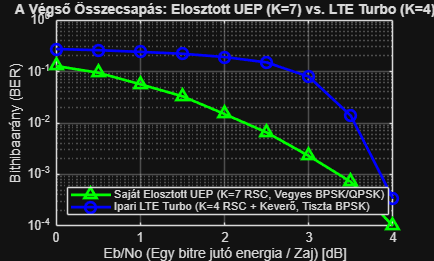


%% --- Eredmények kirajzolása ---
figure('Name', 'UEP vs. LTE Turbo', 'NumberTitle', 'off');
semilogy(EbNo_dB_array, ber_uep, 'g-^', 'LineWidth', 2, 'MarkerSize', 8); hold on;
semilogy(EbNo_dB_array, ber_turbo, 'b-o', 'LineWidth', 2, 'MarkerSize', 8);
grid on;
title('A Végső Összecsapás: Elosztott UEP (K=7) vs. LTE Turbo (K=4)');
xlabel('Eb/No (Egy bitre jutó energia / Zaj) [dB]');
ylabel('Bithibaarány (BER)');
legend('Saját Elosztott UEP (K=7 RSC, Vegyes BPSK/QPSK)', 'Ipari LTE Turbo (K=4 RSC + Keverő, Tiszta BPSK)', 'Location', 'southwest');